% 本代码用于探索并行进行仿真的代码架构

%example 1  
spmd   
A = rand(3,2); %generate a matrix A for each lab(worker)  
end  
A

 
A =
 
   Worker  1: class = double, size = [3  2]
   Worker  2: class = double, size = [3  2]
   Worker  3: class = double, size = [3  2]
   Worker  4: class = double, size = [3  2]
   Worker  5: class = double, size = [3  2]
   Worker  6: class = double, size = [3  2]
   Worker  7: class = double, size = [3  2]
   Worker  8: class = double, size = [3  2]
   Worker  9: class = double, size = [3  2]
   Worker 10: class = double, size = [3  2]
   Worker 11: class = double, size = [3  2]
   Worker 12: class = double, size = [3  2]
   Worker 13: class = double, size = [3  2]
   Worker 14: class = double, size = [3  2]
   Worker 15: class = double, size = [3  2]
   Worker 16: class = double, size = [3  2]
   Worker 17: class = double, size = [3  2]
   Worker 18: class = double, size = [3  2]
   Worker 19: class = double, size = [3  2]
   Worker 20: class = double, size = [3  2]
   Worker 21: class = double, size = [3  2]
   Worker 22: class = double, size = [3  2]
   Worker 23: class = do

A{1}

ans =     0.2621    0.3187
    0.9625    0.3414
    0.8972    0.6596


for i = 1:length(A)  
    figure; imagesc(A{i});   
end  



%example 2  
a = 3;  
b = 4;  
spmd  
    c = spmdIndex();  
    d = c+a;  
end  
c{2} = 5;  
spmd  
    f = c*b;  
end  
f

 
f =
 
   Worker  1: class = double, size = [1  1]
   Worker  2: class = double, size = [1  1]
   Worker  3: class = double, size = [1  1]
   Worker  4: class = double, size = [1  1]
   Worker  5: class = double, size = [1  1]
   Worker  6: class = double, size = [1  1]
   Worker  7: class = double, size = [1  1]
   Worker  8: class = double, size = [1  1]
   Worker  9: class = double, size = [1  1]
   Worker 10: class = double, size = [1  1]
   Worker 11: class = double, size = [1  1]
   Worker 12: class = double, size = [1  1]
   Worker 13: class = double, size = [1  1]
   Worker 14: class = double, size = [1  1]
   Worker 15: class = double, size = [1  1]
   Worker 16: class = double, size = [1  1]
   Worker 17: class = double, size = [1  1]
   Worker 18: class = double, size = [1  1]
   Worker 19: class = double, size = [1  1]
   Worker 20: class = double, size = [1  1]
   Worker 21: class = double, size = [1  1]
   Worker 22: class = double, size = [1  1]
   Worker 23: class = do

for i = 1:length(f)  
    fprintf('%d\t',f{i});%access the value of each lab  
end 

4	20	12	16	20	24	28	32	36	40	44	48	52	56	60	64	68	72	76	80	84	88	92	96	

tic
spmd
k = rand(1,15);
end
k_res = cell(1,length(k));
for i = 1:length(k)
    k_res{i} = k{i};
end
parfor i = 1:length(k_res)
disp(['Index ' num2str(i) ': ' num2str(k_res{i})]);
end

Index 13: 0.021516     0.97558    0.049124     0.49952     0.98666     0.61179    0.017525     0.28058     0.75234     0.41775     0.47764    0.079086     0.96857      0.9344     0.60705
Index 11: 0.16949      0.2021      0.2005     0.49571     0.19762     0.87878     0.28045    0.039072     0.71606    0.010297     0.80294     0.09418     0.33205     0.27442     0.92414
Index 24: 0.38487     0.48095     0.34229     0.82528     0.26113    0.071371     0.62346     0.37606     0.33258     0.56301     0.85657     0.13526     0.31882     0.31498     0.64048
Index 8: 0.79453     0.68588     0.89828     0.39626     0.46872     0.22504     0.18263     0.18885     0.42614     0.23886        0.73     0.90662     0.73619     0.17335     0.45843
Index 10: 0.14485     0.79432     0.33781     0.74047     0.75397     0.11648     0.45712    0.028679     0.33192     0.62599     0.45208     0.65196     0.76578      0.7971     0.17614
Index 2: 0.80271     0.56954     0.26395     0.19346      0.1987     0

toc

历时 0.143573 秒。


caseNumber = 500;
tic
for i = 1:caseNumber
    s = rand(1500).^2;
end
toc

历时 7.016434 秒。


tic
parfor i = 1:caseNumber
    s = rand(1500).^2;
end
toc

历时 0.941054 秒。


%example3 - deal with same Data by different parameters  
%add different values to same array Data  
Data = 1:100;  
spmd  
    switch spmdIndex  
        case 1  
            Data = Data+1;  
        case 2  
            Data = Data+2;  
        otherwise
            Data = Data.^2;
    end  
end  
% print Data{1} & Data{2} for checking 
Data{1}

ans =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


Data{2}

ans =      3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52


Data{3}

ans =            1           4           9          16          25          36          49          64          81         100         121         144         169         196         225         256         289         324         361         400         441         484         529         576         625         676         729         784         841         900         961        1024        1089        1156        1225        1296        1369        1444        1521        1600        1681        1764        1849        1936        2025        2116        2209        2304        2401        2500


%example4   
%add different values for different parts of array Data  
% [1:50]+1  
% [51:100]+2  
Data = 1:100;  
spmd  
    if spmdIndex == 1  
        Data(1:50) = Data(1:50)+1;  
    else  
        Data(51:100) = Data(51:100)+2;  
    end  
end  
Data{1}

ans =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


Data{2}

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


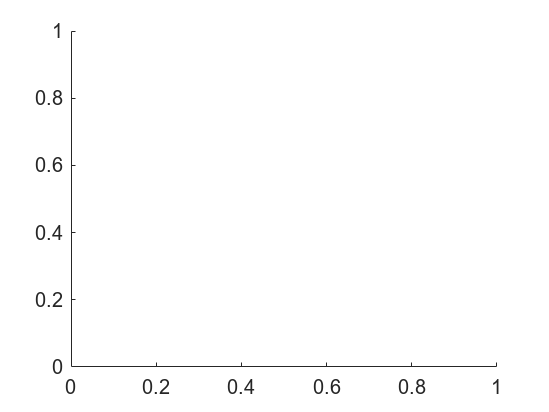


idList = traci.vehicle.getIDList();
figure
hold on
parfor i = 1:100 
end
hold off